## Intro

This scrip try to  using data input to draw residual changing figure.

## Input 1

Total_experiment_number=2000;
step_length=1/50;
sample_length=1/100;

load residual history

data_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.G.D\data\第一轮梯度下降';

Total_residual_history=[];
Total_parameter_history=[];

fileFolder=fullfile(data_location);
dirOutput=dir(fullfile(fileFolder,'*.mat'));
fileNames={dirOutput.name};
n_data_file=length(fileNames);
for i=1:n_data_file
    load([data_location,'\',strcat(fileNames{i})]);
    for j=1:length(residual_history)
        Total_residual_history=[Total_residual_history;residual_history(j)];
        Total_parameter_history=[Total_parameter_history;parmeter_history(j,:)];
    end
end

## Input 2

load residual history

data_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.G.D\data\第二轮梯度下降';

Total_residual_history2=[];
Total_parameter_history2=[];

fileFolder=fullfile(data_location);
dirOutput=dir(fullfile(fileFolder,'*.mat'));
fileNames={dirOutput.name};
n_data_file=length(fileNames);
for i=1:n_data_file
    load([data_location,'\',strcat(fileNames{i})]);
    for j=1:length(residual_history)
        Total_residual_history2=[Total_residual_history2;residual_history(j)];
        Total_parameter_history2=[Total_parameter_history2;parmeter_history(j,:)];
    end
end

## Plotting residual history

%figure
%plot((Total_residual_history)*1e36,'k-o','MarkerFaceColor','k')
%xlabel('step number')
%ylabel('residual/nm^4')
%set(gca,'yscale','log');
%title({'residual change',['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)


## Plotting parameter history

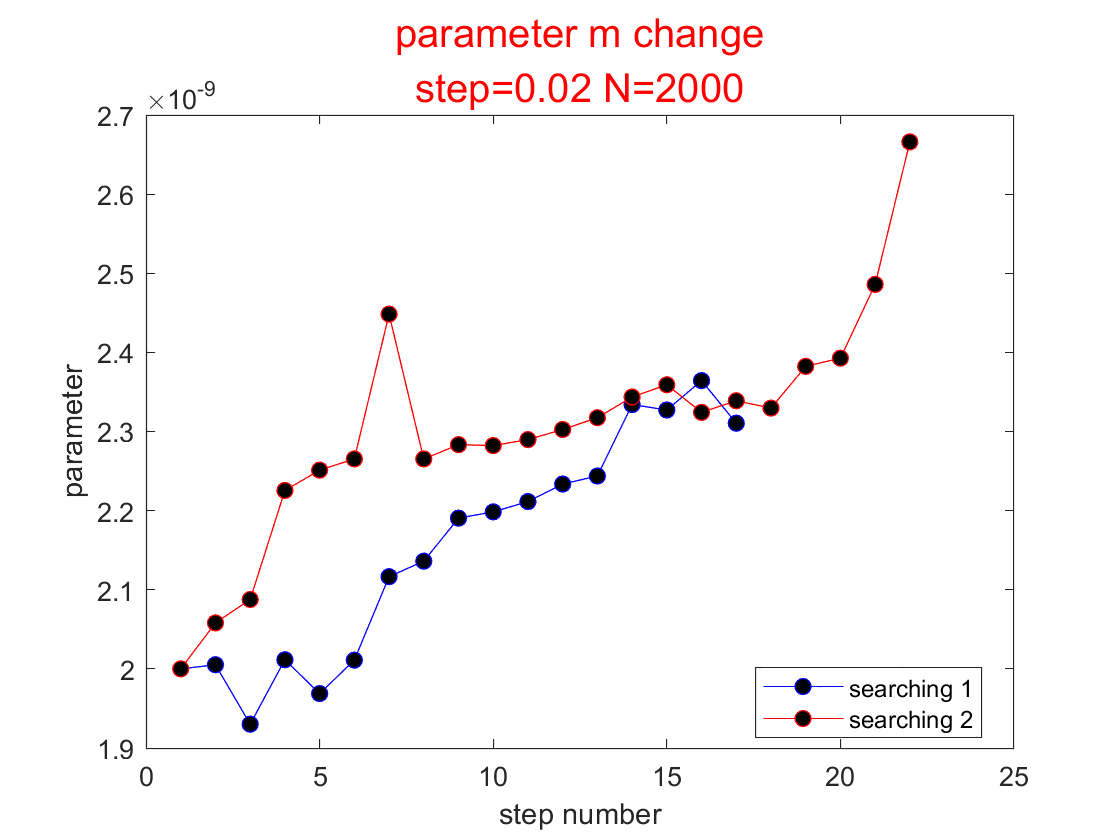

parameter_name='m';
k=1;
figure
plot((Total_parameter_history(:,k)),'k-o','MarkerFaceColor','k','displayname','searching 1',"Color",'b')
hold on
plot((Total_parameter_history2(:,k)),'k-o','MarkerFaceColor','k','displayname','searching 2',"Color",'r')
xlabel('step number')
ylabel('parameter')
title({['parameter ',parameter_name,' change'],['step=',num2str(step_length),' N=',num2str(Total_experiment_number)]},'Color','r','FontSize',15)
legend('Location',"best");